% =========================================================================
%                       Manuel Santos   2019231352
% =========================================================================

clear; close all; clc;

load("Yale.mat");

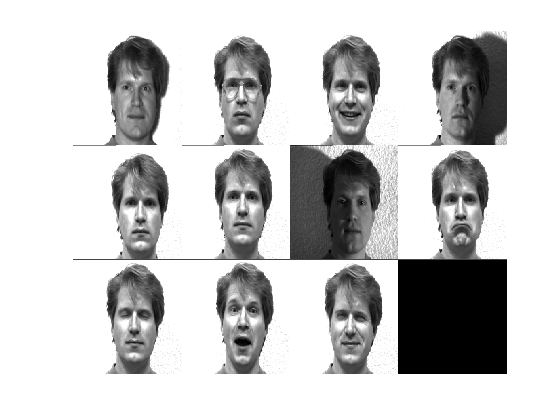

% Show Faces of First Individual
Faces_One = zeros(h_Yale*3,w_Yale*4);
count = 1;
for i=1:3
    for j=1:4
        Faces_One(1+(i-1)*h_Yale:i*h_Yale,1+(j-1)*w_Yale:j*w_Yale) = reshape(allFaces_Yale(:,count),h_Yale,w_Yale);
        count = count + 1;
        if count == 12
            break
        end
    end
end
figure
imagesc(Faces_One),colormap('gray');
axis off; title("All photos from the First Individual")

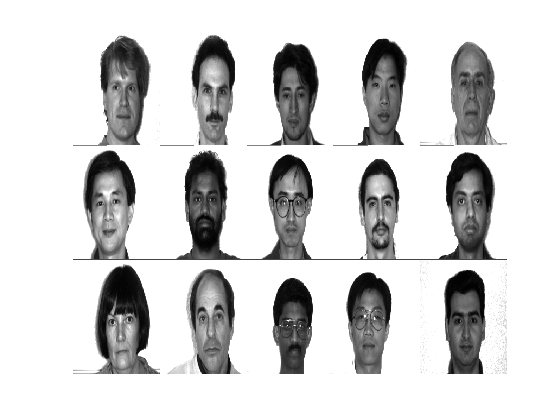

% Show First face of All Individuals
Face_One_All = zeros(h_Yale*3,w_Yale*5);
count = 1;
for i=1:3
    for j=1:5
        Face_One_All(1+(i-1)*h_Yale:i*h_Yale,1+(j-1)*w_Yale:j*w_Yale) = reshape(allFaces_Yale(:,(count-1)*11 + 1),h_Yale,w_Yale);
        count = count + 1;
    end
end
figure
imagesc(Face_One_All),colormap('gray');
axis off; title("First photo from All Individuals")

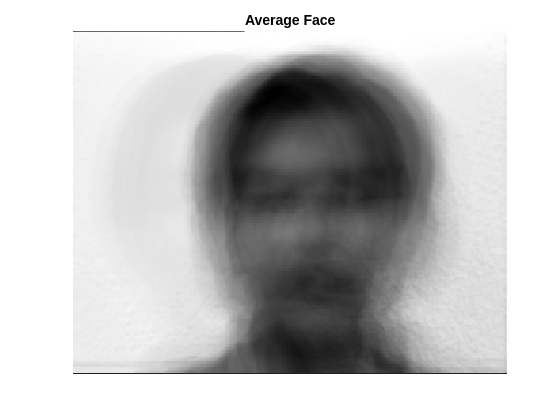

% Select train and test faces
numTrain = 12; % 13, 14 and 15 are for tests
trainFaces = allFaces_Yale(:,1:numPhotosPerSubject_Yale*numTrain);
testFaces = allFaces_Yale(:,numPhotosPerSubject_Yale*numTrain+1:end);

% Calculate average face
avgFace = mean(trainFaces,2);

% Plot average face
figure
imagesc(reshape(avgFace(:),h_Yale,w_Yale));
colormap("gray"); axis off; title("Average Face");

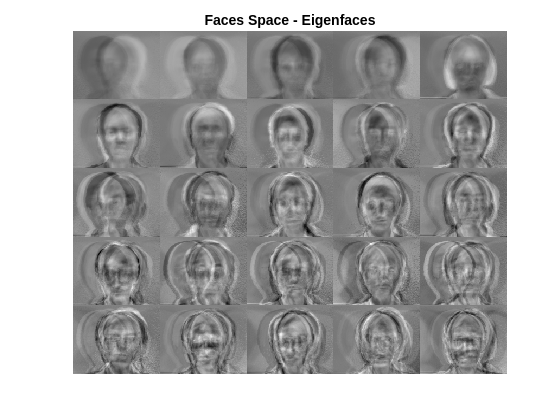

% Calculate SVD
X = double(trainFaces)-avgFace.*ones(size(trainFaces));
[U,S,V] = svd(X,'econ');

% Show Eigenfaces
sizeTile = 5;
EigenFaces = zeros(h_Yale*sizeTile,w_Yale*sizeTile);
count = 1;
for i=1:sizeTile
    for j=1:sizeTile
        EigenFaces(1+(i-1)*h_Yale:i*h_Yale,1+(j-1)*w_Yale:j*w_Yale) = reshape(U(:,count),h_Yale,w_Yale);
        count = count + 1;
    end
end

% Plot Eigenfaces
figure
imagesc(EigenFaces),colormap('gray');
axis off; title("Faces Space - Eigenfaces");

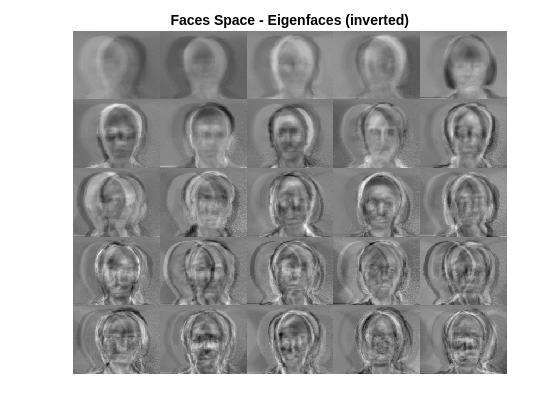


figure
imagesc(EigenFaces.*-1),colormap('gray');
axis off; title("Faces Space - Eigenfaces (inverted)");

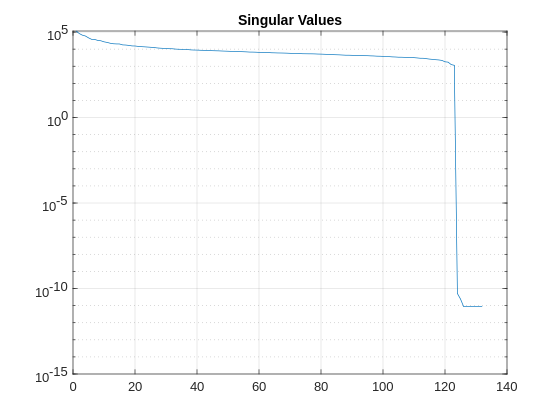

% Show singular values
figure
semilogy(diag(S))
grid on; title("Singular Values");

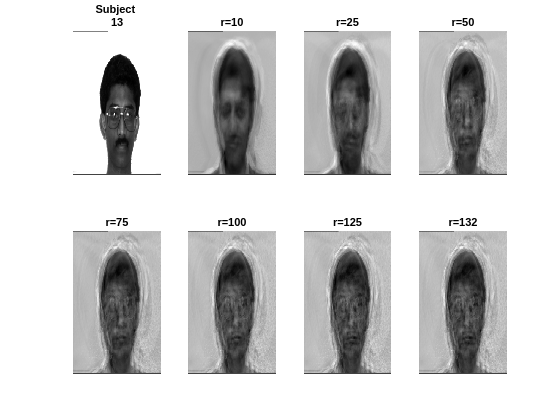

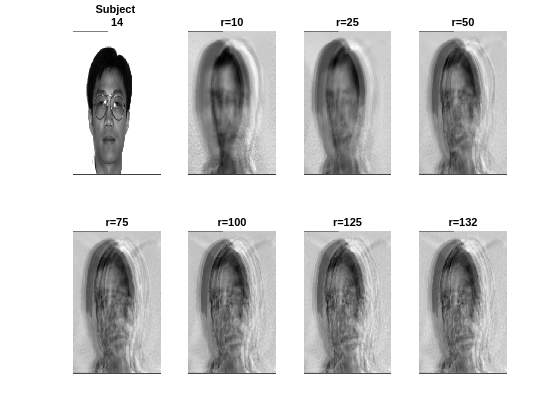

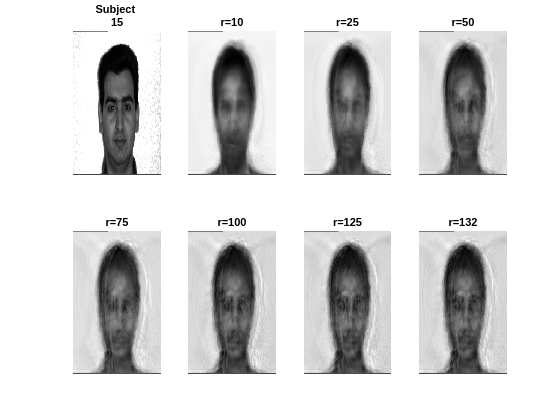

% Reconstruct unseen test face from eigenfaces
 for i = [0,11, 11*2]
    figure
    subplot(2,4,1);
    imagesc(reshape(testFaces(:,i+1),h_Yale,w_Yale));
    colormap("gray"); axis off;
    title(["Subject " num2str(13+(i/11))])
    
    count = 1;
    testFaceMS = double(testFaces(:,i+1)) - avgFace;
    for r=[10 25 50 75 100 125 132]
        count = count + 1;
        subplot(2,4,count);
        reconFace = avgFace + (U(:,1:r)*(U(:,1:r)'*testFaceMS));
        imagesc(reshape(reconFace,h_Yale,w_Yale));
        colormap("gray"); axis off;
        title(['r=' num2str(r,'%d')]);
    end
 end